## Load data

clear;

addpath('functions')
addpath('datasets')

evalId = 10;

% Configurations
config.data.ch = 1;
config.data.rate = 48000; 

config.data.unit = 20; % It might vary depending on the evaluation set

config.data.nLoc = 4;
config.data.nTrialPerLoc = 10;

config.data.recommendedLeng = config.data.rate * .6;

% Load file and cup configurations and update config.data (if needed)
[file, cup, config] = func_loadBasicParams(evalId, config);

config.data.nTrial = config.data.nLoc * config.data.nTrialPerLoc; 
config.data.nData = (ceil(cup.maxAmount / config.data.unit) + 1) * config.data.nTrial; 

% Load data
load([file.name, '.mat']);

% Crop data (if needed)
if length(data(1).raw) > config.data.recommendedLeng
    for cnt = 1:length(data)
        data(cnt).raw = data(cnt).raw(config.data.rate * .1 + (1:config.data.recommendedLeng), :);
    end
end

## Split dataset based on liquid volume

config.calib.nTrain = 29;

[train, test] = func_splitDataset(data, config);

## Select calibration data

config.calib.locSet = [1, 2, 3, 4];
config.calib.nTrialPerTrain = min([5, config.data.nTrialPerLoc * length(config.calib.locSet)]);

curTrain = func_selectCalibrationData(train, config);

## Calibration

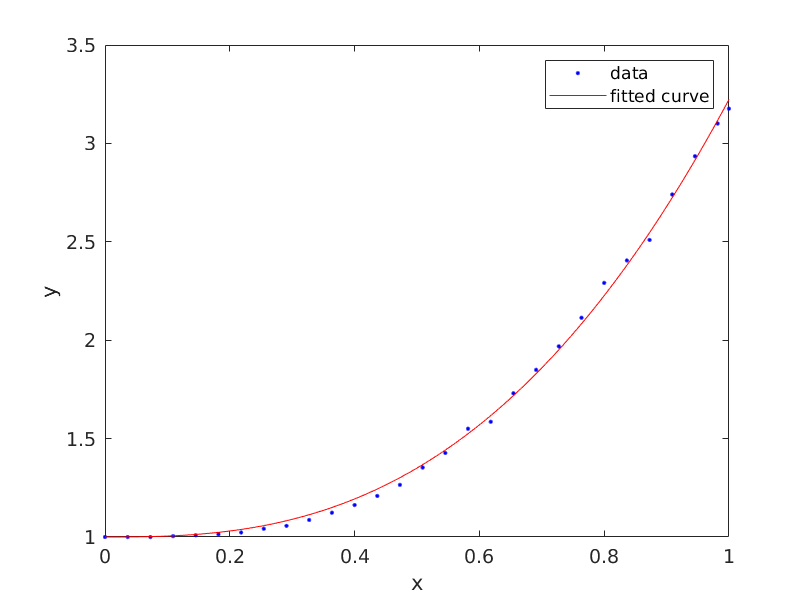

% config.calib.fL = 100;
% config.calib.fH = 1000;
config.calib.initialN = 2;

config.detect.order = 4;
config.detect.energyWidth = config.data.rate * .01;
config.detect.searchRange = config.data.rate * .4;
config.detect.threshold = [.5, .01];
 
config.extract.nfft = config.data.rate * 1;
config.extract.f = (1:config.extract.nfft/2) ./ config.extract.nfft * config.data.rate;
config.extract.marginRatio = .01; 

[b, a] = butter(config.detect.order, [config.calib.fL, config.calib.fH] / config.data.rate * 2, 'bandpass');

curTrain = func_extractFeatures(curTrain, b, a, config);
calib = func_conductCalibration(curTrain, cup, config);

figure
plot(calib.french.f, calib.french.x, calib.french.y)

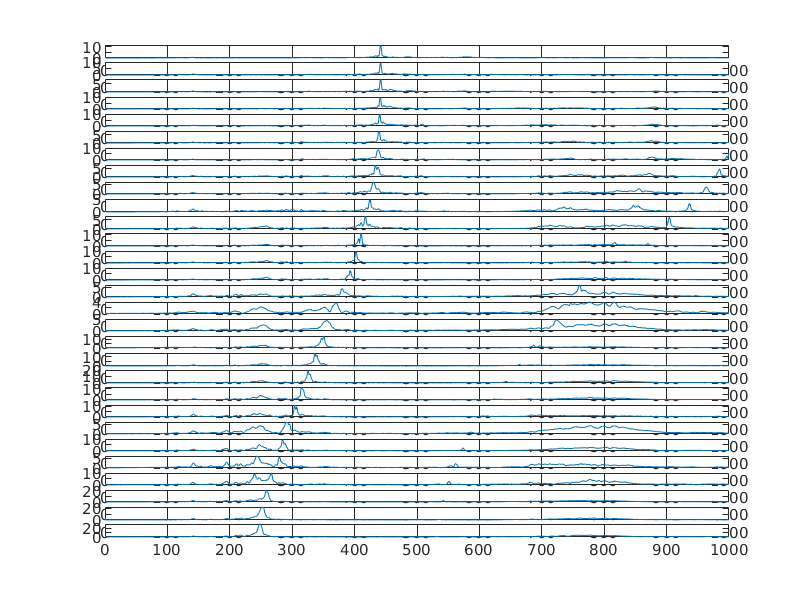


figure
for cnt = 1:config.calib.nTrain
    subplot(config.calib.nTrain, 1, cnt)
    plot(calib.spec(cnt, 1:config.calib.fH))
end

## Extract features in test dataset

[b, a] = butter(config.detect.order, ...
    [min(calib.fL) * (1 - config.extract.marginRatio), max(calib.fH) * (1 + config.extract.marginRatio)] / config.data.rate * 2, ...
    'bandpass');

test = func_extractFeatures(test, b, a, config);

## Select evaluation data and conduct liquid volume measurement

config.eval.locSet = [1, 2, 3, 4];

config.eval.nTrial = min([3, config.data.nTrialPerLoc * length(config.eval.locSet)]);
config.eval.nRepeat = 10;

config.eval.amountSet = unique([test(:).amount]);

evaluate = func_selectEvaluationData(test, config);

evaluate = func_conductMeasurement(evaluate, cup, calib, config);

Unrecognized field name "spec".

Error in func_conductMeasurement (line 4)
    [~, evaluate(cnt).f] = max(evaluate(cnt).spec(ceil(calib.fL * config.extract.nfft / config.data.rate):ceil(calib.fH * config.extract.nfft / config.data.rate)));

## Analyze results

result = struct();
result.raw = [[evaluate(:).amount]', [evaluate(:).eAmount]'];
result.err = abs(result.raw(:, 1) - result.raw(:, 2));
result.avg = mean(result.err);
result.std = std(result.err);

figure
plot(result.err)
title(num2str([result.avg, result.std]));